# A Estimation curve VS different S_EI

## first, setup connctivity map

CurrentFolder = pwd

CurrentFolder = '/home/zx555/Documents/MATLAB/NYU-Vision-main/MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])

N_HC = 3; 
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons; 
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC; 
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6; 

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I
% sparse metrices containing 0 or 1. 
% Row_i Column_j means neuron j projects to neuron i
% add periodic boundary
C_EE = ConnectionMat(N_E,NnE,Size_E,...
                     N_E,NnE,Size_E,...
                     Peak_EE,SD_E,Dist_LB,1);

Elapsed time is 11.831539 seconds.



C_EI = ConnectionMat(N_E,NnE,Size_E,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,0);

Elapsed time is 4.489384 seconds.



C_IE = ConnectionMat(N_I,NnI,Size_I,...
                     N_E,NnE,Size_E,...
                     Peak_I,SD_E,Dist_LB,0);

Elapsed time is 4.067973 seconds.



C_II = ConnectionMat(N_I,NnI,Size_I,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,1);

Elapsed time is 1.490495 seconds.


## Variables and Parameters

%RefTimeE = zeros(N_E,1); VE = 0.5*rand(N_E,1)-0.5; SpE = sparse(N_E,1); GE_ampa_R = zeros(N_E,1); GE_nmda_R = zeros(N_E,1); GE_gaba_R = zeros(N_E,1); GE_ampa_D = zeros(N_E,1); GE_nmda_D = zeros(N_E,1); GE_gaba_D = zeros(N_E,1);
%RefTimeI = zeros(N_I,1); VI = 1.5*rand(N_I,1)-0.5; SpI = sparse(N_I,1); GI_ampa_R = zeros(N_I,1); GI_nmda_R = zeros(N_I,1); GI_gaba_R = zeros(N_I,1); GI_ampa_D = zeros(N_I,1); GI_nmda_D = zeros(N_I,1); GI_gaba_D = zeros(N_I,1); 
load('Initials.mat')
%parameters
S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.029; S_EI = 0.055; S_IE = 0.0081; S_II = 0.048; %Tuned
%S_EE = 0.028; S_EI = 0.056; S_IE = 0.0095; S_II = 0.042; % original
p_EEFail = 0.2; S_amb = 0.01;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms
dt = 0.2;
gL_E = 1/20;  Ve = 14/3; S_Elgn = 0.059; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; S_Ilgn = 0.084; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 
rE_amb = 0.72; rI_amb = 0.36;

% Replace S_EI by testing values
S_EItest = 0.054:0.001:0.068;

## MF estimation: Fix seed/not; MF_free

cluster = gcp('nocreate');
if isempty(cluster)
    cluster = parpool([4 64]);
    cluster.IdleTimeout = 600;
end

% Fr_Fix = zeros(2,length(S_EItest));
% mV_Fix = zeros(2,length(S_EItest));
% tic
% parfor S_EIInd = 1:length(S_EItest)
%     S_EI = S_EItest(S_EIInd);
%     [Fr_Fix(:,S_EIInd),mV_Fix(:,S_EIInd),loop] = MeanFieldEst_BkGd_Indep_FixSeed(C_EE,C_EI,C_IE,C_II,...
%                                                                                  S_EE,S_EI,S_IE,S_II,p_EEFail,...
%                                                                                  lambda_E,S_Elgn,rE_amb,S_amb,...
%                                                                                  lambda_I,S_Ilgn,rI_amb,...
%                                                                                  tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
%                                                                                  rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
%                                                                                  gL_E,gL_I,Ve,Vi,...
%                                                                                  N_HC,n_E_HC,n_I_HC,'End');
%     loop
% end
% toc

% NSample = 50;
% Fr_NoFix = zeros(2,length(S_EItest),NSample);
% mV_NoFix = zeros(2,length(S_EItest),NSample);
% tic
% parfor S_EIInd = 1:length(S_EItest)
%     S_EI = S_EItest(S_EIInd);
%     tic
%     for NInd = 1:NSample
%     [Fr_NoFix(:,S_EIInd,NInd),mV_NoFix(:,S_EIInd,NInd),~] = MeanFieldEst_BkGd_Indep(C_EE,C_EI,C_IE,C_II,...
%                                                                                     S_EE,S_EI,S_IE,S_II,p_EEFail,...
%                                                                                     lambda_E,S_Elgn,rE_amb,S_amb,...
%                                                                                     lambda_I,S_Ilgn,rI_amb,...
%                                                                                     tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
%                                                                                     rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
%                                                                                     gL_E,gL_I,Ve,Vi,...
%                                                                                     N_HC,n_E_HC,n_I_HC,'End');
%     end
%     toc
% end
% toc

Fr_NoFix = zeros(2,length(S_EItest));
mV_NoFix = zeros(2,length(S_EItest));
Fr_NoFixVar = zeros(2,length(S_EItest));
mV_NoFixVar = zeros(2,length(S_EItest));
Fr_NoFixTraj = cell(length(S_EItest),1);
mV_NoFixTraj = cell(length(S_EItest),1);

loopCount = zeros(1,length(S_EItest)); % count the number of loops
ConvIndi = logical(loopCount);

SampleNum = 10;
MaxNum = 200;
tic
parfor S_EIInd = 1:length(S_EItest)
    S_EI = S_EItest(S_EIInd);
    tic
    [Fr_NoFixTraj{S_EIInd},mV_NoFixTraj{S_EIInd},loopCount(S_EIInd),ConvIndi(S_EIInd)]...
                  = MeanFieldEst_BkGd_Indep(C_EE,C_EI,C_IE,C_II,...
                                            S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                            lambda_E,S_Elgn,rE_amb,S_amb,...
                                            lambda_I,S_Ilgn,rI_amb,...
                                            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                            rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                            gL_E,gL_I,Ve,Vi,...
                                            N_HC,n_E_HC,n_I_HC,'End',SampleNum,MaxNum);
                                        
    toc
end
toc

for S_EIInd = 1:length(S_EItest)
    Fr_NoFix(:,S_EIInd) = mean(Fr_NoFixTraj{S_EIInd}(:,end-SampleNum:end),2);
    mV_NoFix(:,S_EIInd) = mean(mV_NoFixTraj{S_EIInd}(:,end-SampleNum:end),2);
    Fr_NoFixVar(:,S_EIInd) = var(Fr_NoFixTraj{S_EIInd}(:,end-SampleNum:end),0,2);
    mV_NoFixVar(:,S_EIInd) = var(mV_NoFixTraj{S_EIInd}(:,end-SampleNum:end),0,2);
end


% Fr_MFFree = zeros(2,length(S_EItest));
% mV_MFFree = zeros(2,length(S_EItest));
% tic
% parfor S_EIInd = 1:length(S_EItest)
%     tic
%     S_EI = S_EItest(S_EIInd);
%     [Fr_MFFree(:,S_EIInd),mV_MFFree(:,S_EIInd),loop] = MFFree_Est_BkGd_Indep(C_EE,C_EI,C_IE,C_II,...
%                                                                                  S_EE,S_EI,S_IE,S_II,p_EEFail,...
%                                                                                  lambda_E,S_Elgn,rE_amb,S_amb,...
%                                                                                  lambda_I,S_Ilgn,rI_amb,...
%                                                                                  tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
%                                                                                  rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
%                                                                                  gL_E,gL_I,Ve,Vi,...
%                                                                                  N_HC,n_E_HC,n_I_HC,'End');
%     loop
%     toc
% end
% toc

% Test RK2
Fr_NoFix_RK2 = zeros(2,length(S_EItest));
mV_NoFix_RK2 = zeros(2,length(S_EItest));
Fr_NoFixVar_RK2 = zeros(2,length(S_EItest));
mV_NoFixVar_RK2 = zeros(2,length(S_EItest));
Fr_NoFixTraj_RK2 = cell(length(S_EItest),1);
mV_NoFixTraj_RK2 = cell(length(S_EItest),1);

loopCount_RK2 = zeros(1,length(S_EItest)); % count the number of loops
ConvIndi_RK2 = logical(loopCount_RK2);

SampleNum_RK2 = 500;
tic
parfor S_EIInd = 1:length(S_EItest)
    S_EI = S_EItest(S_EIInd);
    tic
    [Fr_NoFixTraj_RK2{S_EIInd},mV_NoFixTraj_RK2{S_EIInd},loopCount_RK2(S_EIInd),ConvIndi_RK2(S_EIInd)]...
                  = MeanFieldEst_BkGd_Indep_RK2(C_EE,C_EI,C_IE,C_II,...
                                            S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                            lambda_E,S_Elgn,rE_amb,S_amb,...
                                            lambda_I,S_Ilgn,rI_amb,...
                                            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                            rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                            gL_E,gL_I,Ve,Vi,...
                                            N_HC,n_E_HC,n_I_HC,'End',SampleNum_RK2);
                                        
    toc
end
toc

for S_EIInd = 1:length(S_EItest)
    Fr_NoFix_RK2(:,S_EIInd) = mean(Fr_NoFixTraj_RK2{S_EIInd}(:,end-SampleNum_RK2:end),2);
    mV_NoFix_RK2(:,S_EIInd) = mean(mV_NoFixTraj_RK2{S_EIInd}(:,end-SampleNum_RK2:end),2);
    Fr_NoFixVar_RK2(:,S_EIInd) = var(Fr_NoFixTraj_RK2{S_EIInd}(:,end-SampleNum_RK2:end),0,2);
    mV_NoFixVar_RK2(:,S_EIInd) = var(mV_NoFixTraj_RK2{S_EIInd}(:,end-SampleNum_RK2:end),0,2);
end

## test newton

Fr_Newton = zeros(2,length(S_EItest));
mV_Newton = zeros(2,length(S_EItest));
Fr_NewtonVar = zeros(2,length(S_EItest));
mV_NewtonVar = zeros(2,length(S_EItest));
Fr_NewtonTraj = cell(length(S_EItest),1);
mV_NewtonTraj = cell(length(S_EItest),1);

loopCount_Newton = zeros(1,length(S_EItest)); % count the number of loops
ConvIndi_Newton = logical(loopCount_Newton);

SampleNum = 10;
MaxNum = 200;
StepSize_Newton = 1;
SimuT = 10*1e3;
tic
parfor S_EIInd = 1:length(S_EItest)
    S_EI = S_EItest(S_EIInd);
    tic
    [Fr_NewtonTraj{S_EIInd},mV_NewtonTraj{S_EIInd},loopCount_Newton(S_EIInd),ConvIndi_Newton(S_EIInd)]...
                  = MeanFieldEst_BkGd_Newton2_StepSize_TestmV(C_EE,C_EI,C_IE,C_II,...
                                            S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                            lambda_E,S_Elgn,rE_amb,S_amb,...
                                            lambda_I,S_Ilgn,rI_amb,...
                                            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                            rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                            gL_E,gL_I,Ve,Vi,...
                                            N_HC,n_E_HC,n_I_HC,'End',SampleNum,MaxNum,StepSize_Newton,SimuT);
                                        
    toc
end

Firing rates unconverged
Elapsed time is 13.320402 seconds.
Firing rates unconverged
Elapsed time is 13.956868 seconds.
Firing rates unconverged
Elapsed time is 14.223802 seconds.
Firing rates unconverged
Elapsed time is 14.303484 seconds.
Firing rates unconverged
Elapsed time is 15.044183 seconds.
Firing rates unconverged
Elapsed time is 13.957247 seconds.
Firing rates unconverged
Elapsed time is 13.693078 seconds.
Firing rates unconverged
Elapsed time is 13.715082 seconds.
Firing rates unconverged
Firing rates unconverged
Elapsed time is 14.460655 seconds.
Firing rates unconverged
Firing rates unconverged
Elapsed time is 13.324022 seconds.
Firing rates unconverged
Elapsed time is 9.095040 seconds.
Elapsed time is 13.502703 seconds.
Firing rates unconverged
Elapsed time is 9.340485 seconds.
Elapsed time is 14.108735 seconds.
Firing rates unconverged
Elapsed time is 9.040846 seconds.


toc

Elapsed time is 38.800773 seconds.



for S_EIInd = 1:length(S_EItest)
    Fr_Newton(:,S_EIInd) = mean(Fr_NewtonTraj{S_EIInd}(:,end-SampleNum:end),2);
    mV_Newton(:,S_EIInd) = mean(mV_NewtonTraj{S_EIInd}(:,end-SampleNum:end),2);
    Fr_NewtonVar(:,S_EIInd) = var(Fr_NewtonTraj{S_EIInd}(:,end-SampleNum:end),0,2);
    mV_NewtonVar(:,S_EIInd) = var(mV_NewtonTraj{S_EIInd}(:,end-SampleNum:end),0,2);
end

## Test smaller stepsize


Fr_NoFix_h = zeros(2,length(S_EItest));
mV_NoFix_h = zeros(2,length(S_EItest));
Fr_NoFixVar_h = zeros(2,length(S_EItest));
mV_NoFixVar_h = zeros(2,length(S_EItest));
Fr_NoFixTraj_h = cell(length(S_EItest),1);
mV_NoFixTraj_h = cell(length(S_EItest),1);

loopCount_h = zeros(1,length(S_EItest)); % count the number of loops
ConvIndi_h = logical(loopCount_h);

SampleNum = 10;
MaxNum = 200;
h = 1;
SimuT = 10*1e3;
tic
parfor S_EIInd = 1:length(S_EItest)
    S_EI = S_EItest(S_EIInd);
    tic
    [Fr_NoFixTraj_h{S_EIInd},mV_NoFixTraj_h{S_EIInd},loopCount_h(S_EIInd),ConvIndi_h(S_EIInd)]...
                  = MeanFieldEst_BkGd_Indep_StepSize(C_EE,C_EI,C_IE,C_II,...
                                            S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                            lambda_E,S_Elgn,rE_amb,S_amb,...
                                            lambda_I,S_Ilgn,rI_amb,...
                                            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                            rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                            gL_E,gL_I,Ve,Vi,...
                                            N_HC,n_E_HC,n_I_HC,'End',SampleNum,MaxNum,h,SimuT);
                                        
    toc
end

Elapsed time is 1.210428 seconds.
Elapsed time is 1.398383 seconds.
Elapsed time is 1.609201 seconds.
Firing rates unconverged
Elapsed time is 3.473377 seconds.
Elapsed time is 2.902409 seconds.
Firing rates unconverged
Elapsed time is 3.761084 seconds.
Firing rates unconverged
Elapsed time is 3.712692 seconds.
Firing rates unconverged
Elapsed time is 3.409655 seconds.
Firing rates unconverged
Elapsed time is 2.942634 seconds.
Firing rates unconverged
Firing rates unconverged
Elapsed time is 2.681840 seconds.
Elapsed time is 0.334733 seconds.
Firing rates unconverged
Elapsed time is 2.808144 seconds.
Firing rates unconverged
Elapsed time is 2.114409 seconds.
Elapsed time is 2.641425 seconds.
Firing rates unconverged
Elapsed time is 1.840122 seconds.


toc

Elapsed time is 9.712767 seconds.



for S_EIInd = 1:length(S_EItest)
    Fr_NoFix_h(:,S_EIInd) = mean(Fr_NoFixTraj_h{S_EIInd}(:,end-SampleNum:end),2);
    mV_NoFix_h(:,S_EIInd) = mean(mV_NoFixTraj_h{S_EIInd}(:,end-SampleNum:end),2);
    Fr_NoFixVar_h(:,S_EIInd) = var(Fr_NoFixTraj_h{S_EIInd}(:,end-SampleNum:end),0,2);
    mV_NoFixVar_h(:,S_EIInd) = var(mV_NoFixTraj_h{S_EIInd}(:,end-SampleNum:end),0,2);
end


## Network Simulation

S_EE = 0.033, S_EI = 0.054, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

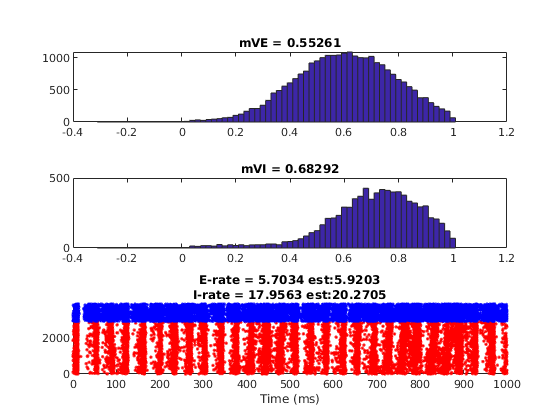

S_EE = 0.033, S_EI = 0.054, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.054, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

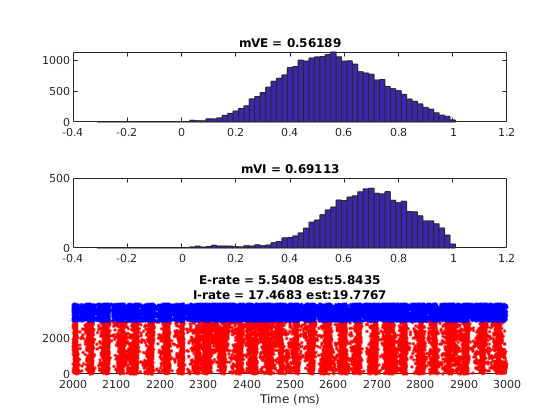

S_EE = 0.033, S_EI = 0.055, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

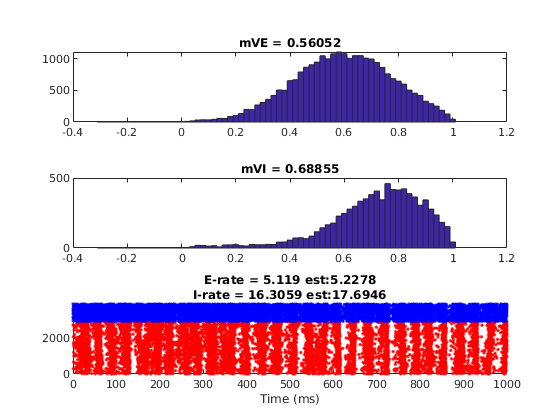

S_EE = 0.033, S_EI = 0.055, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.055, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

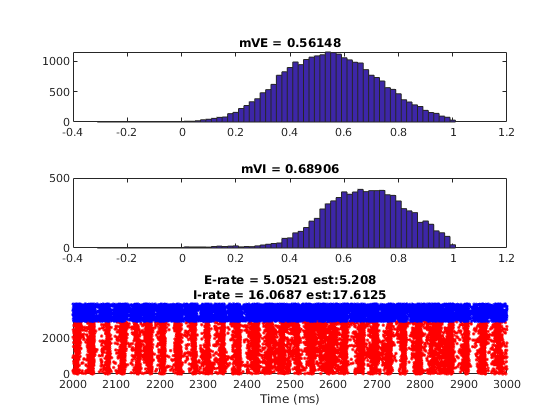

S_EE = 0.033, S_EI = 0.056, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

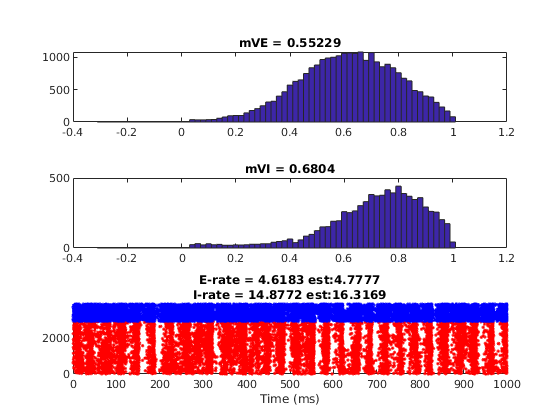

S_EE = 0.033, S_EI = 0.056, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.056, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

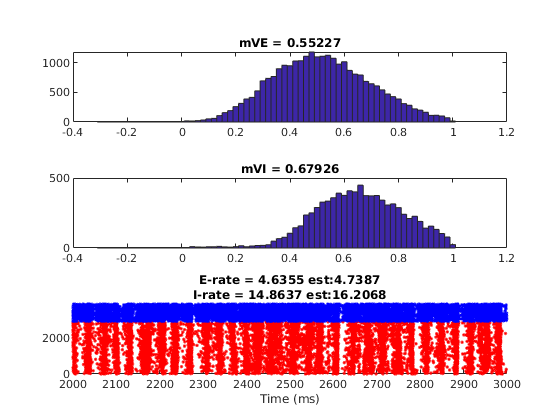

S_EE = 0.033, S_EI = 0.057, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

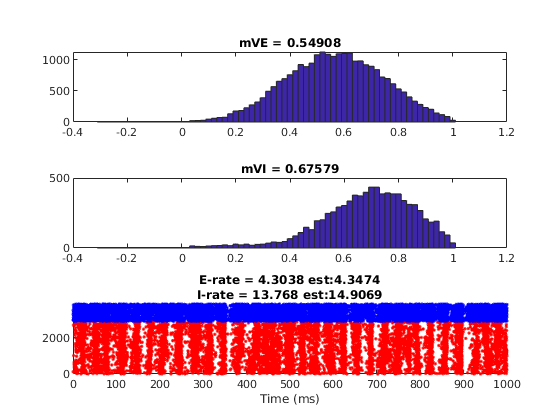

S_EE = 0.033, S_EI = 0.057, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.057, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

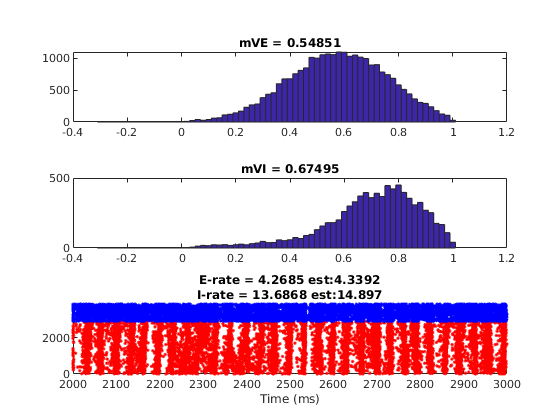

S_EE = 0.033, S_EI = 0.058, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

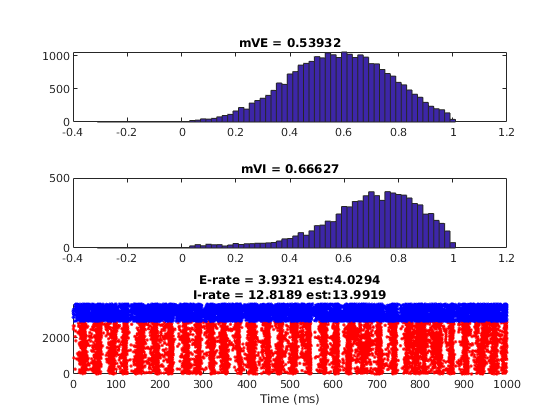

S_EE = 0.033, S_EI = 0.058, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

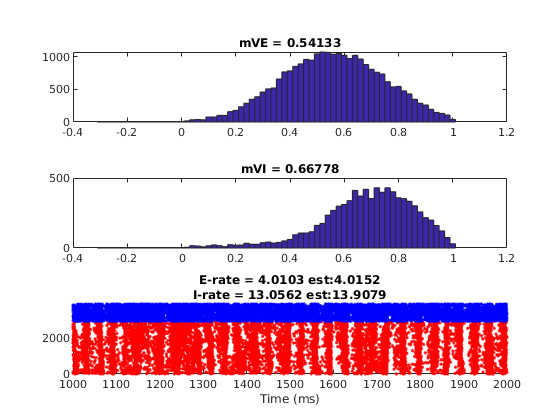

S_EE = 0.033, S_EI = 0.058, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.059, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.059, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.059, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.06, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.06, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.06, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

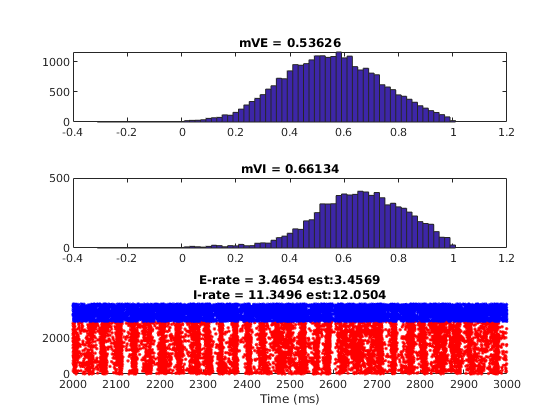

S_EE = 0.033, S_EI = 0.061, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

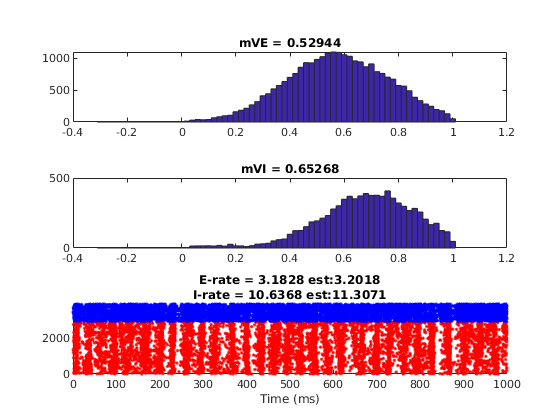

S_EE = 0.033, S_EI = 0.061, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.061, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.062, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.062, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.062, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

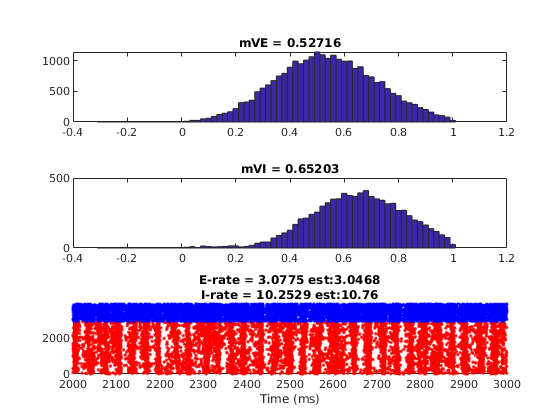

S_EE = 0.033, S_EI = 0.063, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

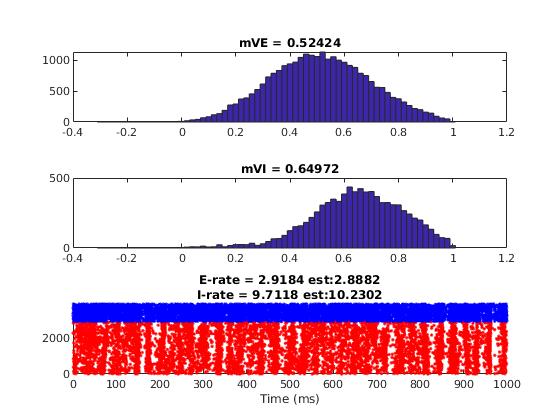

S_EE = 0.033, S_EI = 0.063, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

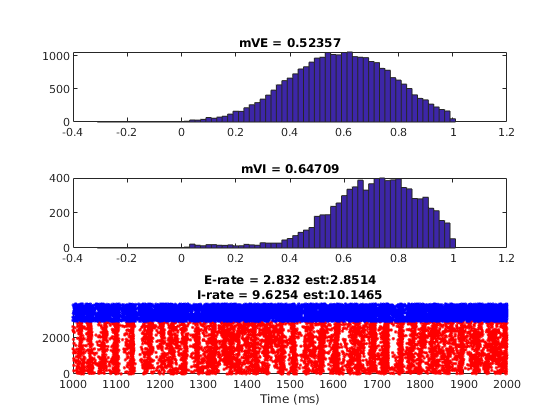

S_EE = 0.033, S_EI = 0.063, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.064, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.064, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.064, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

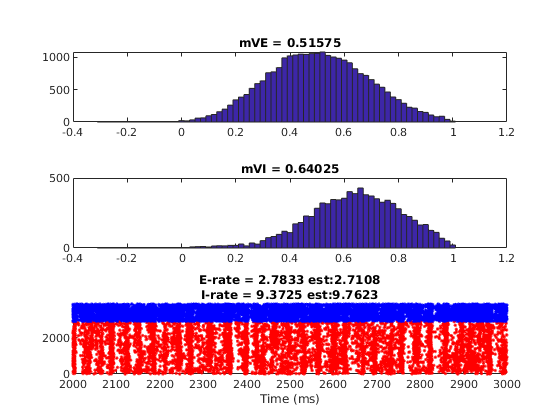

S_EE = 0.033, S_EI = 0.065, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.065, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.065, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

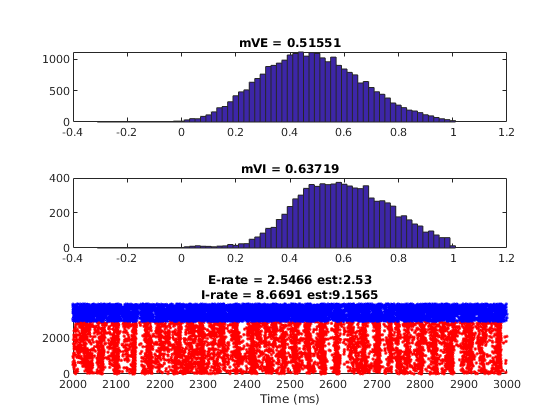

S_EE = 0.033, S_EI = 0.066, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

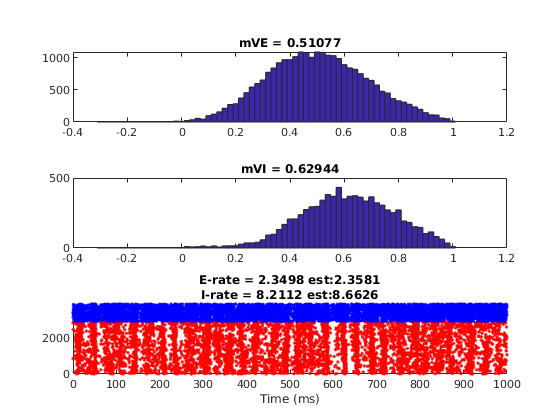

S_EE = 0.033, S_EI = 0.066, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.066, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.067, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

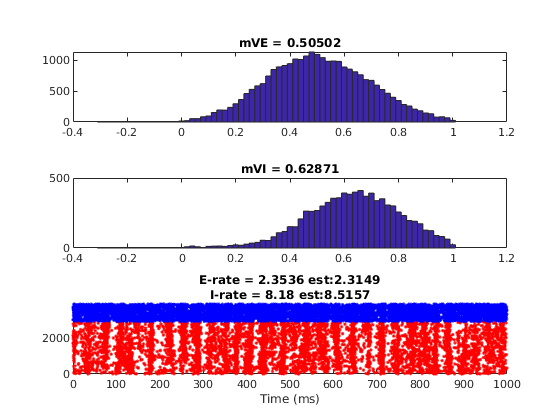

S_EE = 0.033, S_EI = 0.067, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

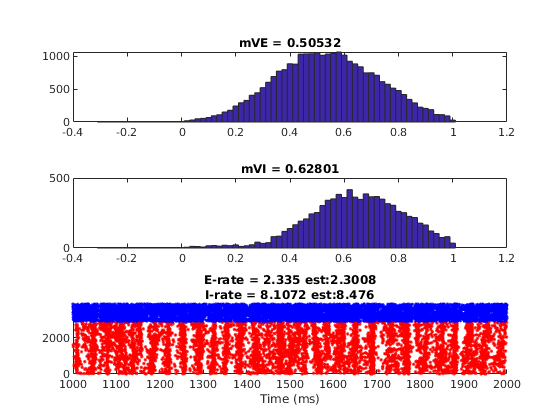

S_EE = 0.033, S_EI = 0.067, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.068, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.068, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.068, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

T = 3000; sampleT = 2; SimulationT = 1000;

Fr_NW = zeros(2,length(S_EItest));
mV_NW = zeros(2,length(S_EItest));

E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
    
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2)); 
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

for S_EIInd = 1:length(S_EItest)
    S_EI = S_EItest(S_EIInd);
    %E_SpHis= []; I_SpHis=[];
    E_Sp = []; I_Sp = [];
    VE_T = []; VI_T = [];
    sampleN = floor(sampleT/dt); % sample each 2 ms
    SimulationN = floor(SimulationT/dt); % show and check every 200ms
    for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,...
          oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
     oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
          oGI_ampa_D,oGI_nmda_D,oGI_gaba_D] = ...
          V1NetworkUpdate(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,...
                                          GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                          RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                          GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                          C_EE,C_EI,C_IE,C_II,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
                          S_amb,lambda_E,lambda_I,rE_amb,rI_amb);
                      
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
                                              GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
                                              GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;

% When reaching every 200ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>500
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
                         ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
                         'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
                         ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
                         'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
    
    fprintf(ParameterDisp)
    h = figure(1);
    subplot 311
    hist(oVE,-0.3:0.02:1)
    title(['mVE = ' num2str(nanmean(VE_T))])
    %E_SpHis = [E_SpHis,sum(oSpE)];
    %axis([-0.4 1.1 0 6000])
    
    subplot 312
    hist(oVI,-0.3:0.02:1)
    title(['mVI = ' num2str(nanmean(VI_T))])
    %I_SpHis = [I_SpHis,sum(oSpI)];
    %axis([-0.4 1.1 0 2000])
    
    

    %E_Ind = 10000:13000; I_Ind = 3300:4300;
    scatterE = find(ismember(E_Sp(:,1),E_Ind));
    scatterI = find(ismember(I_Sp(:,1),I_Ind));
    [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
    [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);

    WinSize = SimulationT;
    T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
    E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
    I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
    E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
    I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);

    f_EnIOneStep = MeanFieldEst_BkGd(N_EE,N_EI,N_IE,N_II,...
                                     S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                     lambda_E,S_Elgn,rE_amb,S_amb,...
                                     lambda_I,S_Ilgn,rI_amb,...
                                     gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));

    subplot 313
    hold on
    scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
    scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
    title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
    xlabel('Time (ms)')
    xlim(T_RateWindow)
    ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
    drawnow
    %pause
    close(h)
    end

    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    if sum(isnan(oVE))>0.6*N_E
        error('warning!: Network exploded')
    end
    end
    Fr_NW(:,S_EIInd) = [E_Rate;I_Rate];
    mV_NW(:,S_EIInd) = [nanmean(VE_T),nanmean(VI_T)];
end

## Plot Curves: Comparing MF estimates and network simulations

MFSampleN = 50;
figure('Name','MFEstimation VS Network Simulation')
subplot 411
hold on
%plot(S_EItest,Fr_Fix(1,:),'g')
%scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(Fr_NoFix(1,:,1:MFSampleN)),...
%                                    length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,Fr_NoFix(1,:),'r--')
errorbar(S_EItest,Fr_NoFix(1,:),Fr_NoFixVar(1,:),'r')
plot(S_EItest,Fr_NW(1,:),'k','Marker','o')
xlabel('S_{EI}'); ylabel('f_E')
legend('MF+LIF','var of MF','Network Simulation')
xlim([min(S_EItest) max(S_EItest)])

subplot 412
hold on
% plot(S_EItest,Fr_Fix(2,:),'g')
% scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(Fr_NoFix(2,:,1:MFSampleN)),...
%                                     length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,Fr_NoFix(2,:),'r--')
errorbar(S_EItest,Fr_NoFix(2,:),Fr_NoFixVar(2,:),'r')
plot(S_EItest,Fr_NW(2,:),'k','Marker','o')
xlabel('S_{EI}'); ylabel('f_I')
xlim([min(S_EItest) max(S_EItest)])


 mean Vs

subplot 413
hold on
% plot(S_EItest,mV_Fix(1,:),'g')
% scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(mV_NoFix(1,:,1:MFSampleN)),...
%                                     length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,mV_NoFix(1,:),'r--')
errorbar(S_EItest,mV_NoFix(1,:),mV_NoFixVar(1,:),'r')
plot(S_EItest,mV_NW(1,:),'k','Marker','o')
xlabel('S_{EI}'); ylabel('mV_E')
legend('MF+LIF','var of MF','Network Simulation')
xlim([min(S_EItest) max(S_EItest)])

subplot 414
hold on
% plot(S_EItest,mV_Fix(2,:),'g')
% scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(mV_NoFix(2,:,1:MFSampleN)),...
%                                     length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,mV_NoFix(2,:),'r--')
errorbar(S_EItest,mV_NoFix(2,:),mV_NoFixVar(1,:),'r')
plot(S_EItest,mV_NW(2,:),'k','Marker','o')
xlabel('S_{EI}'); ylabel('mV_I')
xlim([min(S_EItest) max(S_EItest)])

## Compare Newton results

MFSampleN = 50;
figure('Name','MFEstimation VS Network Simulation')
subplot 411
hold on
%plot(S_EItest,Fr_Fix(1,:),'g')
%scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(Fr_NoFix(1,:,1:MFSampleN)),...
%                                    length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,Fr_Newton(1,:),'r--')
errorbar(S_EItest,Fr_Newton(1,:),Fr_NewtonVar(1,:),'r')
plot(S_EItest,Fr_NW(1,:),'k','Marker','o')
xlabel('S_{EI}'); ylabel('f_E')
legend('MF+LIF','var of MF','Network Simulation')
xlim([min(S_EItest) max(S_EItest)])

subplot 412
hold on
% plot(S_EItest,Fr_Fix(2,:),'g')
% scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(Fr_Newton(2,:,1:MFSampleN)),...
%                                     length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,Fr_Newton(2,:),'r--')
errorbar(S_EItest,Fr_Newton(2,:),Fr_NewtonVar(2,:),'r')
plot(S_EItest,Fr_NW(2,:),'k','Marker','o')
xlabel('S_{EI}'); ylabel('f_I')
xlim([min(S_EItest) max(S_EItest)])


 mean Vs

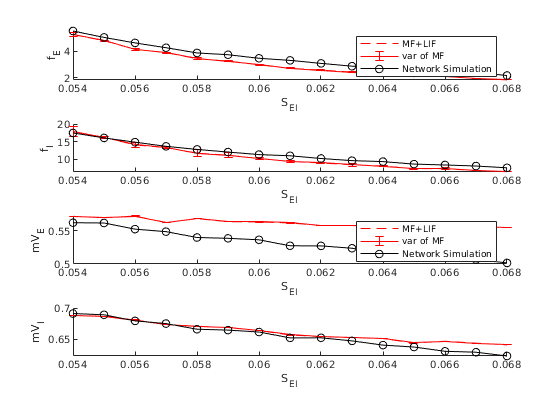

subplot 413
hold on
% plot(S_EItest,mV_Fix(1,:),'g')
% scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(mV_Newton(1,:,1:MFSampleN)),...
%                                     length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,mV_Newton(1,:),'r--')
errorbar(S_EItest,mV_Newton(1,:),mV_NewtonVar(1,:),'r')
plot(S_EItest,mV_NW(1,:),'k','Marker','o')
xlabel('S_{EI}'); ylabel('mV_E')
legend('MF+LIF','var of MF','Network Simulation')
xlim([min(S_EItest) max(S_EItest)])

subplot 414
hold on
% plot(S_EItest,mV_Fix(2,:),'g')
% scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(mV_Newton(2,:,1:MFSampleN)),...
%                                     length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,mV_Newton(2,:),'r--')
errorbar(S_EItest,mV_Newton(2,:),mV_NewtonVar(1,:),'r')
plot(S_EItest,mV_NW(2,:),'k','Marker','o')
xlabel('S_{EI}'); ylabel('mV_I')
xlim([min(S_EItest) max(S_EItest)])

figure('Name','Trajectories-Last')
subplot 131
plot_dir(Fr_NoFixTraj{2}(1,end-100:end)',Fr_NoFixTraj{2}(2,end-100:end)');
xlabel('fE');ylabel('fI')
axis([3 7 12 22])
title('last 100 iterations')

subplot 132
plot_dir(Fr_NoFixTraj{2}(1,end-50:end)',Fr_NoFixTraj{2}(2,end-50:end)');
xlabel('fE');ylabel('fI')
axis([3 7 12 22])
title('last 50 iterations')

subplot 133
plot_dir(Fr_NoFixTraj{2}(1,end-15:end)',Fr_NoFixTraj{2}(2,end-15:end)');
xlabel('fE');ylabel('fI')
axis([3 7 12 22])
title('last 15 iterations')

figure('Name','Trajectories-Every 50')
for subInd = 1:floor(SampleNum/50)
    subplot(2,5,subInd)
    plot_dir(Fr_NoFixTraj{2}(1,end-50*(11-subInd):end-50*(10-subInd))',Fr_NoFixTraj{2}(2,end-50*(11-subInd):end-50*(10-subInd))');
    hold on
    plot(mean(Fr_NoFixTraj{2}(1,end-50*(11-subInd):end-50*(10-subInd))'), ...
         mean(Fr_NoFixTraj{2}(2,end-50*(11-subInd):end-50*(10-subInd))'),...
         '+','MarkerSize',15,'LineWidth',2)
    hold off
    xlabel('fE');ylabel('fI')
    axis([3 7 12 22])
    title(['iterations:' num2str(50*(subInd-1)+1) '-' num2str(50*subInd)])
end
    
figure('Name','Means of Every 50')
plotx = mean(reshape(Fr_NoFixTraj{2}(1,end-499:end)',50,10));
ploty = mean(reshape(Fr_NoFixTraj{2}(2,end-499:end)',50,10));
plot(plotx, ploty)

## %% Results for different h

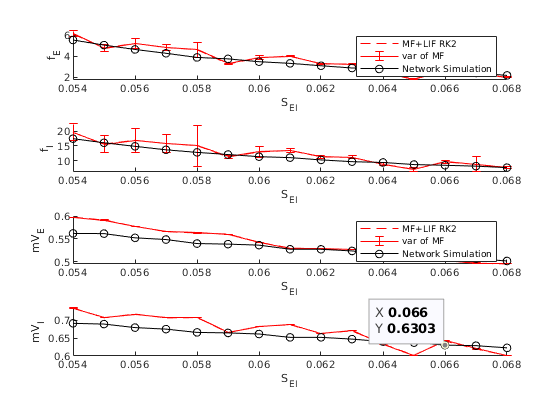

figure('Name','MFEstimation VS Network Simulation')
subplot 411
hold on
%plot(S_EItest,Fr_Fix(1,:),'g')
%scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(Fr_NoFix(1,:,1:MFSampleN)),...
%                                    length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,Fr_NoFix_h(1,:),'r--')
errorbar(S_EItest,Fr_NoFix_h(1,:),Fr_NoFixVar_h(1,:),'r')
plot(S_EItest,Fr_NW(1,:),'k','Marker','o')
xlabel('S_{EI}'); ylabel('f_E')
legend('MF+LIF RK2','var of MF','Network Simulation')
xlim([min(S_EItest) max(S_EItest)])

subplot 412
hold on
% plot(S_EItest,Fr_Fix(2,:),'g')
% scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(Fr_NoFix(2,:,1:MFSampleN)),...
%                                     length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,Fr_NoFix_h(2,:),'r--')
errorbar(S_EItest,Fr_NoFix_h(2,:),Fr_NoFixVar_h(2,:),'r')
plot(S_EItest,Fr_NW(2,:),'k','Marker','o')
xlabel('S_{EI}'); ylabel('f_I')
xlim([min(S_EItest) max(S_EItest)])

subplot 413
hold on
% plot(S_EItest,mV_Fix(1,:),'g')
% scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(mV_NoFix(1,:,1:MFSampleN)),...
%                                     length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,mV_NoFix_h(1,:),'r--')
errorbar(S_EItest,mV_NoFix_h(1,:),mV_NoFixVar_h(1,:),'r')
plot(S_EItest,mV_NW(1,:),'k','Marker','o')
xlabel('S_{EI}'); ylabel('mV_E')
legend('MF+LIF RK2','var of MF','Network Simulation')
xlim([min(S_EItest) max(S_EItest)])

subplot 414
hold on
% plot(S_EItest,mV_Fix(2,:),'g')
% scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(mV_NoFix(2,:,1:MFSampleN)),...
%                                     length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,mV_NoFix_h(2,:),'r--')
errorbar(S_EItest,mV_NoFix_h(2,:),mV_NoFixVar_h(1,:),'r')
plot(S_EItest,mV_NW(2,:),'k','Marker','o')
xlabel('S_{EI}'); ylabel('mV_I')
xlim([min(S_EItest) max(S_EItest)])

figure('Name','Trajectories-h')
subplot 131
plot_dir(Fr_NoFixTraj_h{2}(1,end-100:end)',Fr_NoFixTraj_h{2}(2,end-100:end)');
xlabel('fE');ylabel('fI')
axis([3 7 12 22])
title('last 100 iterations')

subplot 132
plot_dir(Fr_NoFixTraj_h{2}(1,end-50:end)',Fr_NoFixTraj_h{2}(2,end-50:end)');
xlabel('fE');ylabel('fI')
axis([3 7 12 22])
title('last 50 iterations')

subplot 133
plot_dir(Fr_NoFixTraj_h{2}(1,end-15:end)',Fr_NoFixTraj_h{2}(2,end-15:end)');
xlabel('fE');ylabel('fI')
axis([3 7 12 22])
title('last 15 iterations')

plotNum = 500; % when plot samples and actual dismatch
figure('Name','Trajectories-Every 50-h')
for subInd = 1:floor(plotNum/50)
    subplot(2,5,subInd)
    plot_dir(Fr_NoFixTraj_h{2}(1,end-50*(11-subInd):end-50*(10-subInd))',Fr_NoFixTraj_h{2}(2,end-50*(11-subInd):end-50*(10-subInd))');
    hold on
    plot(mean(Fr_NoFixTraj_h{2}(1,end-50*(11-subInd):end-50*(10-subInd))'), ...
         mean(Fr_NoFixTraj_h{2}(2,end-50*(11-subInd):end-50*(10-subInd))'),...
         '+','MarkerSize',15,'LineWidth',2)
    hold off
    xlabel('fE');ylabel('fI')
    axis([3 7 12 22])
    title(['iterations:' num2str(50*(subInd-1)+1) '-' num2str(50*subInd)])
end
    
figure('Name','Means of Every 50')
plotx = mean(reshape(Fr_NoFixTraj_h{2}(1,end-499:end)',50,10));
ploty = mean(reshape(Fr_NoFixTraj_h{2}(2,end-499:end)',50,10));
plot(plotx, ploty)

## Compare hs for single trajectories

figure('Name','Traj-time for different hs')
subplot 221
testInd = 1;
hold on
plot(Fr_NoFixTraj{testInd}(1,:),'r-')
plot(Fr_NoFixTraj{testInd}(2,:),'b-')
plot(Fr_NoFixTraj_h{testInd}(1,:),'r--')
plot(Fr_NoFixTraj_h{testInd}(2,:),'b--')
hold off
title(['S_{EE} = ' num2str(S_EE) ', S_{EI} = ' num2str(S_EItest(testInd)) ...
                         ', S_{IE} = ' num2str(S_IE) ', S_{II} = ' num2str(S_II)])
ylabel('firing rates')                  

subplot 222
testInd = 5;
hold on
plot(Fr_NoFixTraj{testInd}(1,:),'r-')
plot(Fr_NoFixTraj{testInd}(2,:),'b-')
plot(Fr_NoFixTraj_h{testInd}(1,:),'r--')
plot(Fr_NoFixTraj_h{testInd}(2,:),'b--')
hold off
title(['S_{EE} = ' num2str(S_EE) ', S_{EI} = ' num2str(S_EItest(testInd)) ...
                         ', S_{IE} = ' num2str(S_IE) ', S_{II} = ' num2str(S_II)])
                     
varQuot1 = Fr_NoFixVar_h/Fr_NoFixVar; 
subplot(2,4,[6,7])
hold on
plot(S_EItest,Fr_NoFixVar(1,:),'r-')
plot(S_EItest,Fr_NoFixVar(2,:),'b-')
plot(S_EItest,Fr_NoFixVar_h(1,:),'r--')
plot(S_EItest,Fr_NoFixVar_h(2,:),'b--')
hold off
legend('fE, h = 1','fI, h = 1','fE, h = 0.1','fE, h = 0.1')
set(gca,'YScale','log')
ylabel('vars of fr estimates')